# Projet de restauration d’images : deuxième partie

## 1. Déconvolution d’un signal triangulaire : approche matricielle et approximation circulante

#### On considère maintenant la version du produit de convolution

#### Definir des parametres：

clear all
close all
disp('----------------------------------------------------');

----------------------------------------------------


disp('1D: la version du produit de convolution');

1D: la version du produit de convolution


L1x = 100;	    % duree d'observation du signal d'entree (en s)
fe = 1;		    % frequence d'echantillonnage (Hz)
Te = 1/fe;		% periode d'echantillonnage
N1x = L1x/Te;	% nombre de points du signal x
kx = 0:N1x-1;	    % vecteur des indices temporels  
tx= kx*Te;		% vecteur des instants d'echantillonnage

%x:un signal triangulair
k1 = 0:N1x/2-1;
t1 = k1*Te;
x1 = t1/(L1x/2); 
k2 = N1x/2:N1x-1;  % modif  N1x-1 => N1x
t2 = k2*Te;
x2 = (-t2 + L1x)/(L1x/2);
x = [x1 x2];
subplot(2,3,1)
plot(tx,x);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal entree x(t)');

%h: filtre gaussien
mu_h=15*Te;
sigma=4;
sigma_h=sigma*Te;
L_h=30*Te;
t_h=(0:Te:L_h);
N_h=length(t_h);
h=(1/(sigma_h*sqrt(2*pi)))*exp(-(((t_h-mu_h)/(sqrt(2)*sigma_h)).*((t_h-mu_h)/(sqrt(2)*sigma_h))));
subplot(2,3,2)
plot(t_h,h)
xlabel('temps (s)'); ylabel('amplitude'); title('Reponse impulsionnelle h(t)');

% H:Construction de la matrice H de convolution (Toeplitz)
N_x=length(x);
N_y = N_x;
hcol_1 = zeros(1,N_x);
hlig_1 = zeros(1,N_x);  
hlig_1(1:N_h) = hlig_1(1:N_h) + flip(h);
hcol_1(1,1) = hlig_1(1,1);
H = toeplitz(hcol_1,hlig_1);
cond_H(sigma)=cond(H);%返回 2-范数逆运算的条件数，等于 A 的最大奇异值与最小奇异值之比。

%y:Convolution de x et h
y_nb=conv(x,h);
N1=length(y_nb);
k=0:1:N1-1;
t=k*Te;
subplot(2,3,3)
plot(t,y_nb)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie non bruite y_{nb}(t)');

%y:Convolution sous forme matricielle y_nb = H x 和上面求解一样
y_nb=H*(x');
k=0:1:N_y-1;
t=k*Te;
subplot(2,3,3)
plot(t,y_nb)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie non bruite y_{nb}(t)');

% w: bruit additif gaussien
RSB=10;
y=adgnoise(y_nb,RSB);
% Representation du bruit (gaussien)
w = y - y_nb;
RSB_y=10*log10((y'*y/N_y)/var(w))

RSB_y = 10.7022

subplot(2,3,5)
plot(t,w); 
xlabel('temps (s)'); ylabel('amplitude'); title('Bruit w(t)');

% representation temporelle du signal de sortie bruite
subplot(2,3,6)
stairs(t,y);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie bruite y(t)');

## 1.1 Moindres carrés

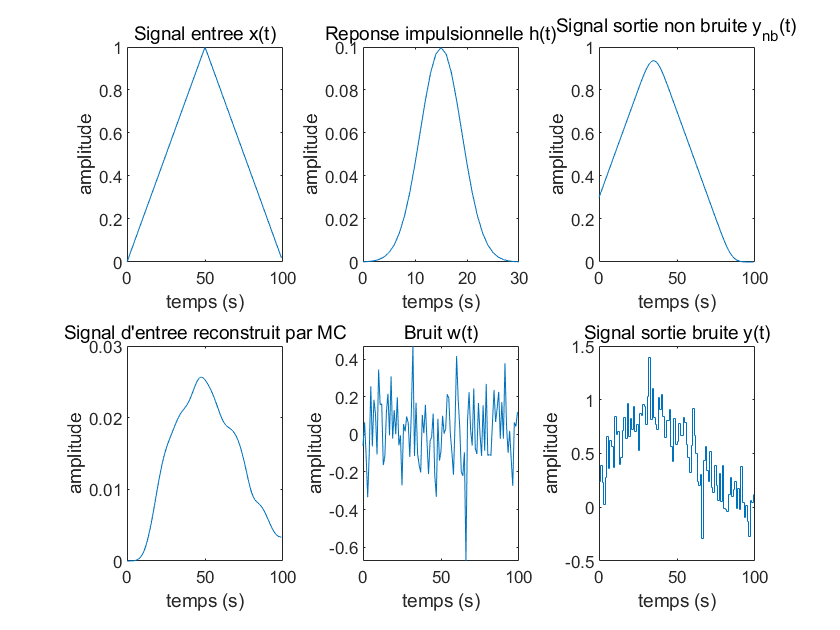

L_x = 100;	    % duree d'observation du signal d'entree
fe = 1;		    % frequence d'echantillonage
Te = 1/fe;		% periode d'echantillonage
N_x = L_x/Te;	% nombre de points du signal x
k_x = 0:N_x-1;	% index temporel
t_x= k_x*Te;    % base de temps
% 7. Deconvolution l2 par moindres carree
%--------------------------------------------------------------------------
x_rec= mldivide(y,H); %inv(H)*y; %执行 x = A\B 这一操作的替代方法，但很少使用。
%--------------------------------------------------------------------------
subplot(2,3,4)
plot(t_x,x_rec)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit par MC');

## 1.3 Algorithme(cette procédure correspond exactement à l’algorithme de « déconvolution naïve » programmé dans la Partie 1.)

disp('----------------------------------------------------');

----------------------------------------------------


disp('1D: la version du filtrage inverse');

1D: la version du filtrage inverse


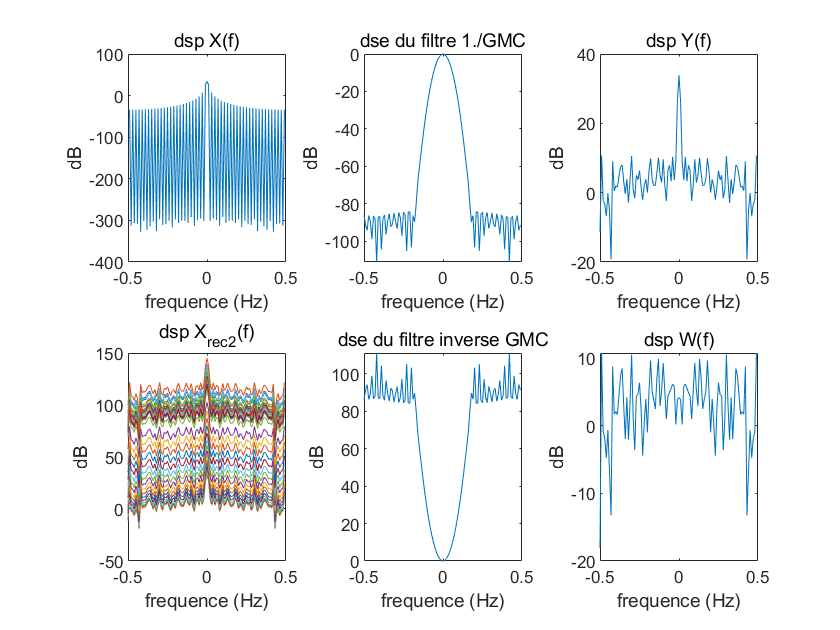

%1.Reponse en frequence du filtre
N=N_x;
n = -N/2:N/2-1;
f = n*fe/N;
H_TFD = fft(h,N_x);
% % Résolution par approximation circulante
% bcol_1 = zeros(1,N_x);
% blig_1 = zeros(1,N_x);  
% bcol_1(1:N_h) = bcol_1(1:N_h) + h;
% blig_1(1,1) = bcol_1(1,1);
% B = toeplitz(hlig_1,hcol_1);
% H_circu=H;
% H_circu(end-29:end,1:30)=B(1:30,1:30);
% e_H_circu=eig(H_circu);
% GMC=1./e_H_circu;

H2 = H_TFD.*conj(H_TFD);
GMC1 = conj(H_TFD)./(H2);

figure(2); subplot(2,3,2)
plot(f,fftshift(20*log10(abs(1./GMC1))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre 1./GMC');

%2.  TFD X du signal d'entree, TFD Y du signal de sortie, TFD X_rec du signal reconstruit 
X = fft(x,N);
subplot(2,3,1)
plot(f,fftshift(20*log10(abs(X))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp X(f)');

Y = fft(y,N); % spectre du signal bruite
%Y=fft(y_nb,N); % spectre du signal non bruite
subplot(2,3,3)
plot(f,fftshift(20*log10(abs(Y))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp Y(f)');

%3. % Reponse en frequence du filtre inverse
Hinv = GMC1;
hinv = real(ifft(Hinv));%用快速傅里叶变换算法计算Y 的逆离散傅里叶变换。
subplot(2,3,5)
plot(f,fftshift(20*log10(abs(Hinv))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre inverse GMC');

%4.1 Reponse en frequence du bruit de quantification
W = fft(w,N);
subplot(2,3,6)
plot(f,fftshift(20*log10(abs(W))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp W(f)');

%4.2 calcul du signal reconstruit par filtrage inverse
X_rec2 = Y.*GMC1;
subplot(2,3,4)
plot(f,fftshift(20*log10(abs(X_rec2))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp X_{rec2}(f)');

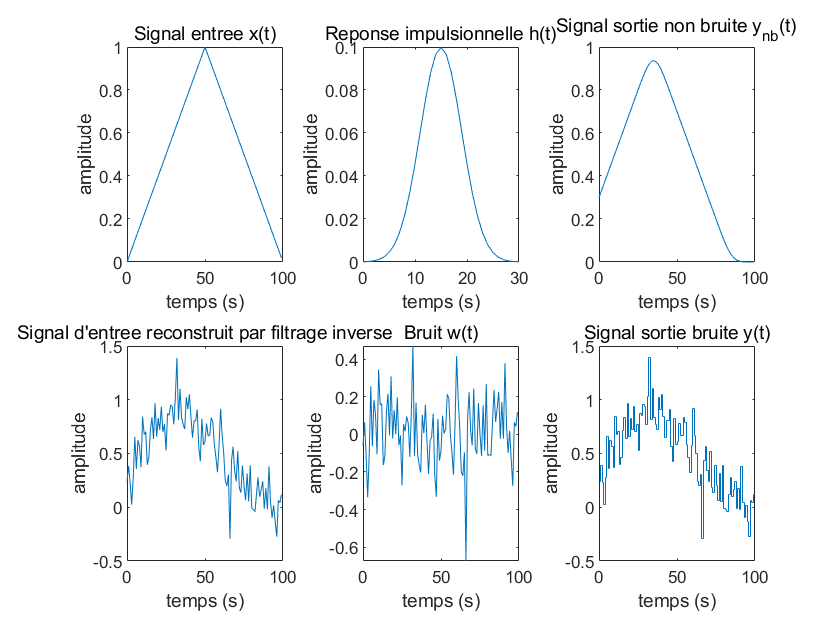


x_rec2 = real(ifft(X_rec2));

Nrec2=length(x_rec2);
krec2=0:1:Nrec2-1;
trec2=krec2*Te;
figure(1);
subplot(2,3,4)
plot(trec2(1:length(x)),x_rec2(1:length(x)))
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit par filtrage inverse');

## 1.4 Régularisation et douceur

% % Construction de la matrice D1 de differentiation
% dcol_1 = zeros(1,N_x);
% dcol_1(1:2) = dcol_1(1:2) + [1 -1];
% dlig_1 = zeros(1,N_x);  
% dlig_1(1,1) = dcol_1(1,1);
% D1 = toeplitz(dlig_1,dcol_1);
% D1_circu=D1;
% D1_circu(100,1)=-1;

d=[1;-1];
D=fft(h,N_x);

## 1.5 Approximation circulante

disp('----------------------------------------------------');

----------------------------------------------------


disp('1D: la version du MCR');

1D: la version du MCR


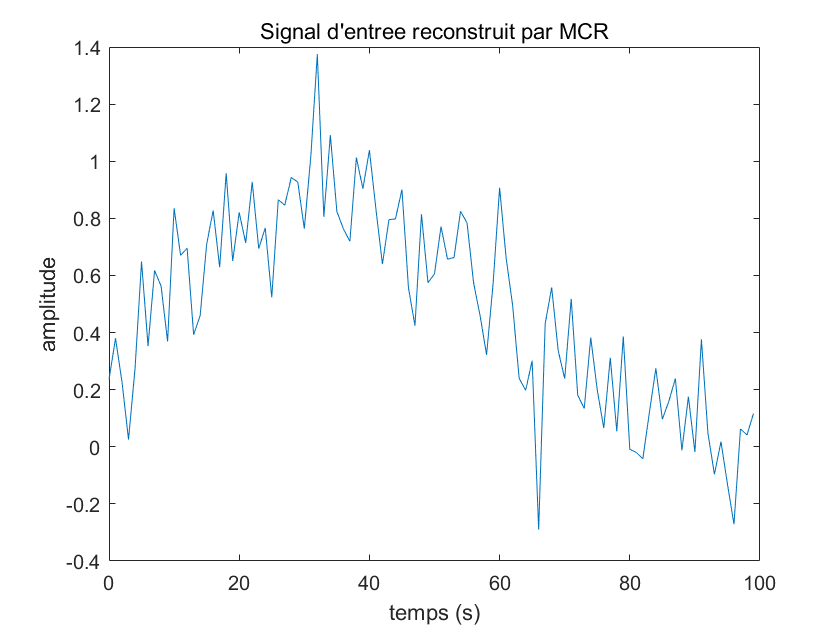

% %coefficeient de regulation
% alpha= .00000001;
% % le vecteur gMCR
% e_D1_circu=eig(D1_circu);
% e_H2=e_H_circu.*conj(e_H_circu);
% e_D2=e_D1_circu.*conj(e_D1_circu);
% GMCR=conj(e_H_circu)./(e_H2+alpha*e_D2);
alpha1 = .01;

D2 = D.*conj(D);
GMCR1 = conj(H_TFD)./(H2+alpha1*D2);

X_rec3 = Y.*GMCR1;
x_rec3 = real(ifft(X_rec3));

Nrec3=length(x_rec3);
krec3=0:1:Nrec3-1;
trec3=krec3*Te;
figure(3);
plot(trec3(1:length(x)),x_rec3(1:length(x)))
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit par MCR');

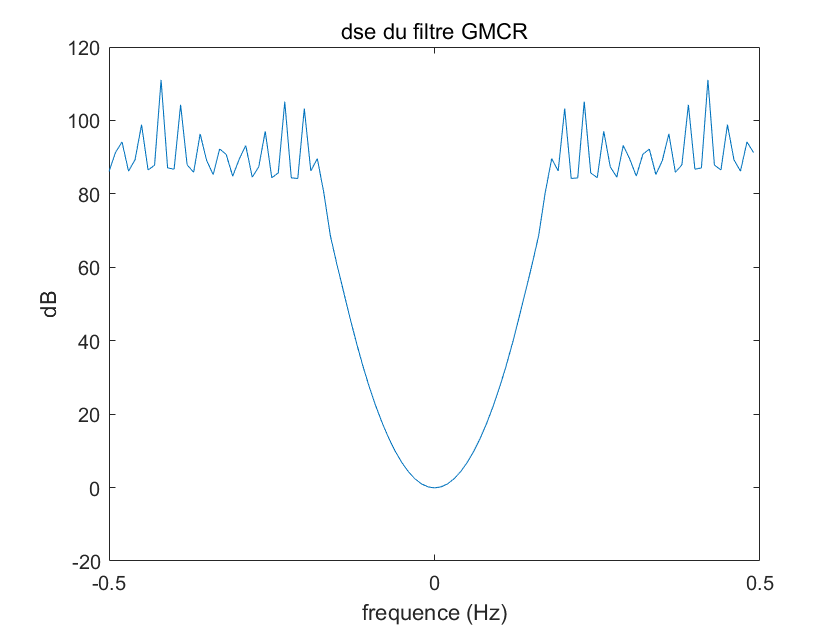


plot(f,fftshift(20*log10((abs(GMCR1)))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre GMCR');

% Calculer la solution régularisée x（a）
% Intervalle de variation du coefficient de regularisation
min_alpha=-10;
pas_alpha=0.1;
max_alpha=+2;
i_alpha=0;

%faire varier alpha--choix "optimal"

for var_alpha=min_alpha:pas_alpha:max_alpha
    alpha=10^var_alpha;
    i_alpha=i_alpha+1;
    GMCR1 = conj(H_TFD)./(H2+alpha*D2);
    X_rec3 = Y.*GMCR1;
    x_rec3 = real(ifft(X_rec3));
    %--------------------------------------------------------------------------
    x_rec_l2(:,i_alpha) = x_rec3(1:length(x));
    %--------------------------------------------------------------------------
    err_rec(:,i_alpha)=x'-x_rec_l2(:,i_alpha);
    Werr_rec(i_alpha)=err_rec(:,i_alpha)'*err_rec(:,i_alpha);%energie de erreur de reconstruction
end

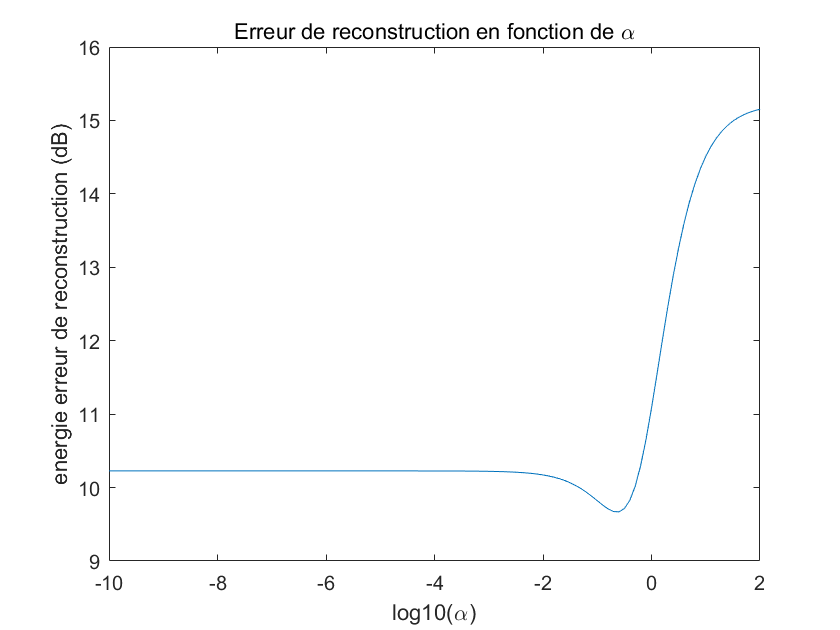

% energie de l'erreur de reconstruction en fonction du coefficient de regularisation
figure
var_alpha=min_alpha:pas_alpha:max_alpha;
plot(var_alpha,10*log10(Werr_rec))
xlabel('log10(\alpha)'); ylabel('energie erreur de reconstruction (dB)'); title('Erreur de reconstruction en fonction de \alpha');


[W_err_rec_min,i_alpha_opt] = min(Werr_rec);
alpha_opt=10^(min_alpha+pas_alpha*(i_alpha_opt-1))

alpha_opt = 0.2512

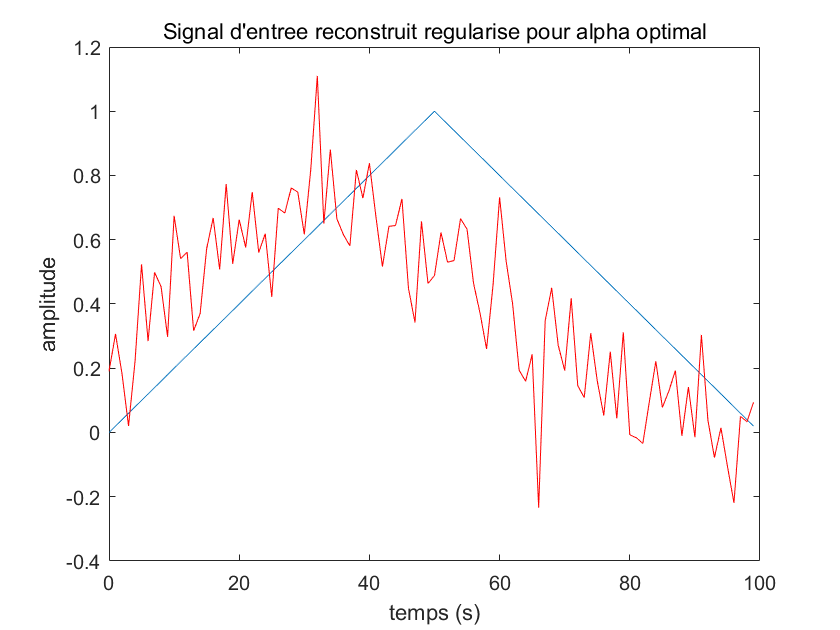

figure
plot(t_x,x)
hold on
plot(t_x,x_rec_l2(:,i_alpha_opt),'r')
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit regularise pour alpha optimal');
hold off

## 2. Restauration d’images

disp('----------------------------------------------------');

----------------------------------------------------


disp('2D image');

2D image


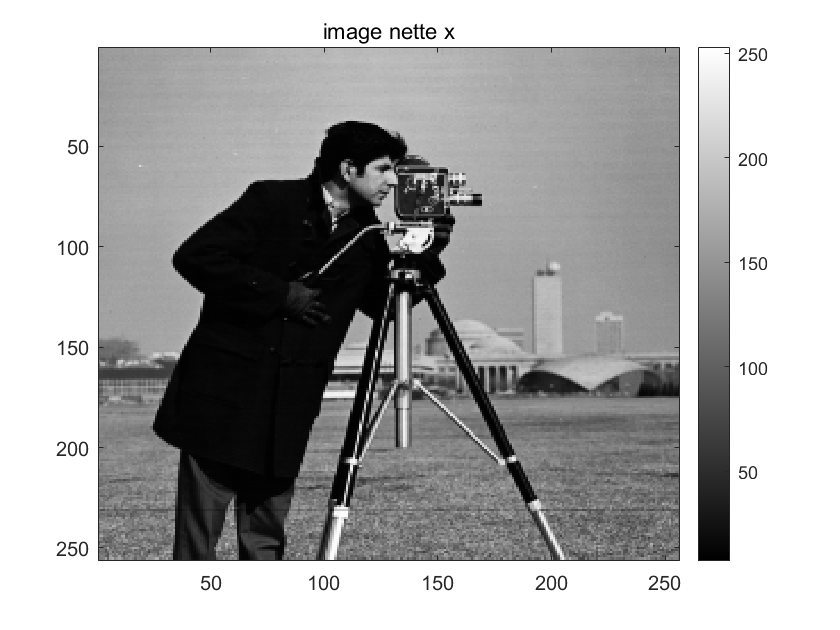


% Modélisation du problème direct
clear all
close all
A=imread('cameraman.tif');
A=double(A);
figure,imagesc(A),colormap(gray),colorbar,title('image nette x')

lh=5;
h= 1/(lh^2)*ones(lh);
d=[0 -1 0;-1 4 -1; 0 -1 0];

B_nb=conv2(A,h,'same');
N_B=size(B_nb,1);
%un bruit additif blanc et gaussien
RSB=20

RSB = 20

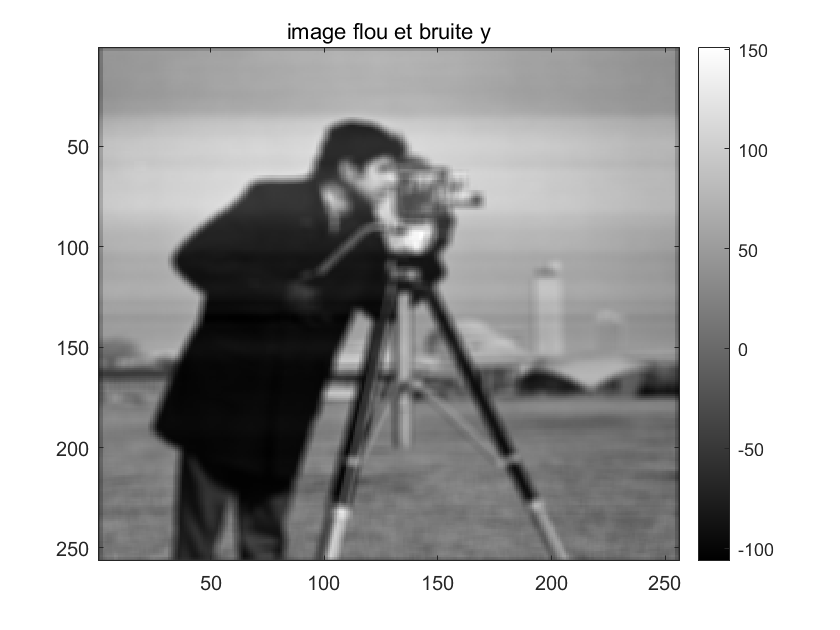

B=adgnoise(B_nb,RSB);
figure,imagesc(B),colormap(gray),colorbar,title('image flou et bruite y')

## 2.3.2 Mise en oeuvre de la déconvolution

### (1)les moindres carrés simples

disp('----------------------------------------------------');

----------------------------------------------------


disp('2D: la version du MC');

2D: la version du MC


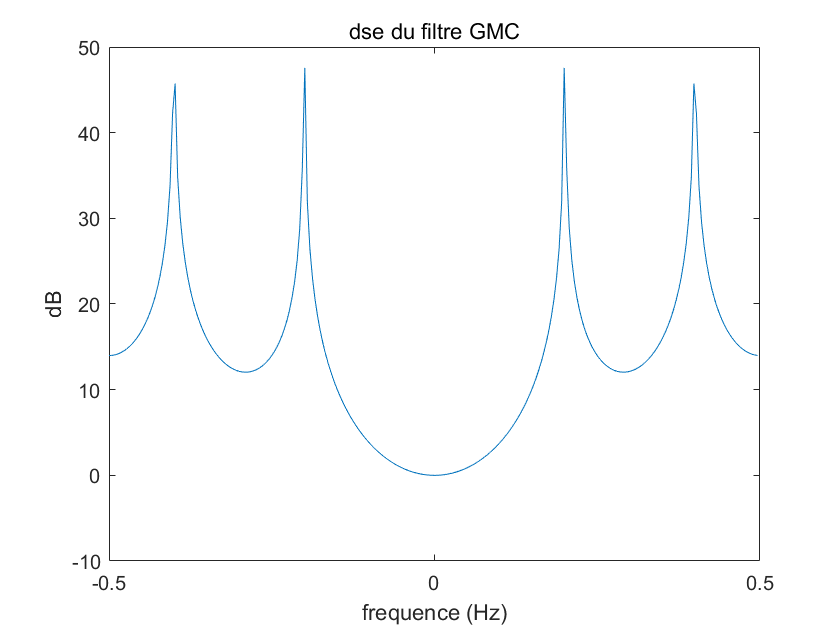


fe = 1;		    % frequence d'echantillonage
Te = 1/fe;		% periode d'echantillonage
N = N_B;
n = -N/2:N/2-1;
f = n*fe/N;

H=fft2(h,size(A,1),size(A,2));
D=fft2(d,size(A,1),size(A,2));

H2 = H.*conj(H);
GMC = conj(H)./(H2);

plot(f,fftshift(20*log10(abs(mean(GMC)))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre GMC');

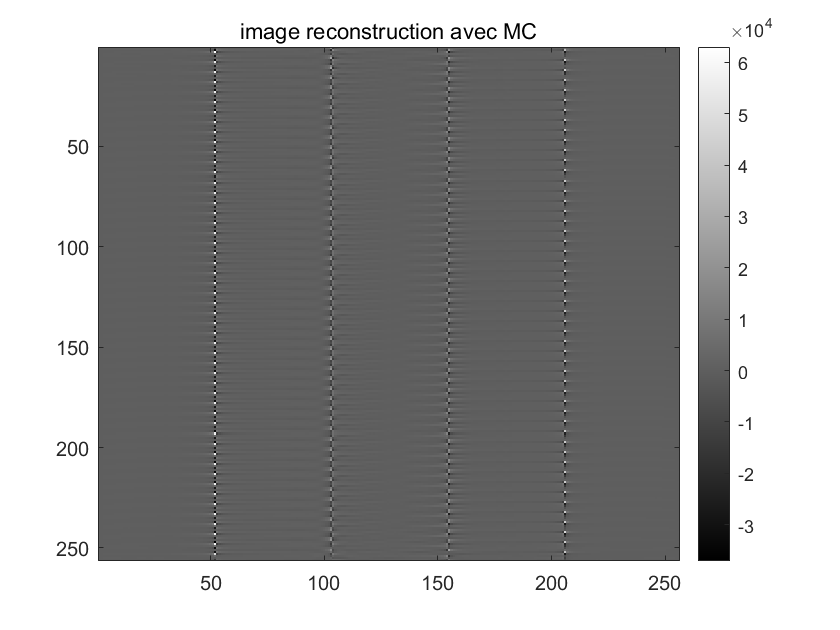


A_rec_f = B.*GMC;
A_rec = real(ifft(A_rec_f));
figure,imagesc(A_rec),colormap(gray),colorbar,title('image reconstruction avec MC')

### (2)les moindres carrés régularisés

disp('----------------------------------------------------');

----------------------------------------------------


disp('2D: la version du MCR');

2D: la version du MCR


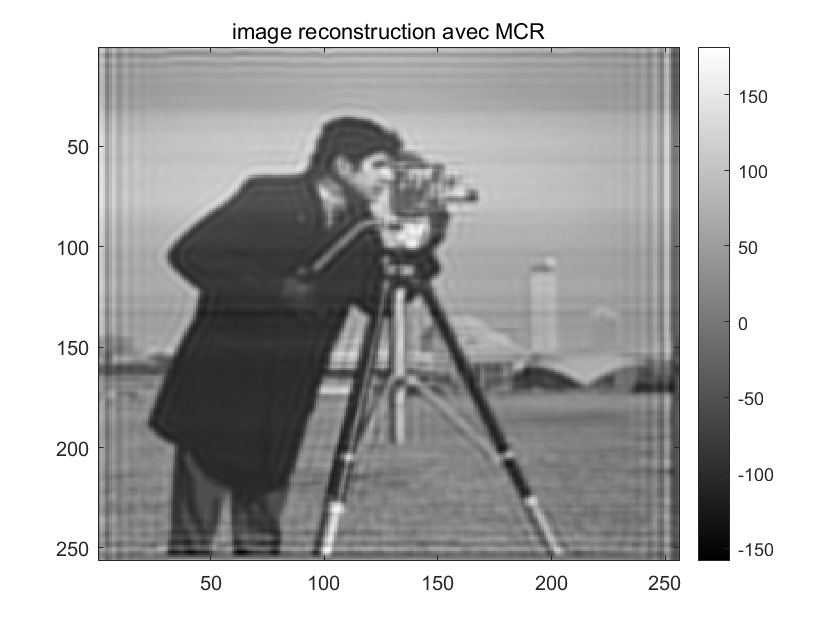

alpha = .01;
H2 = H.*conj(H);
D2 = D.*conj(D);
GMCR = conj(H)./(H2+alpha*D2);

Y=fft2(B);
X=Y.*GMCR;

Arec=real(ifft2(X));
figure,imagesc(Arec),colormap(gray),colorbar,title('image reconstruction avec MCR')

% Calculer la solution régularisée x（a）
% Intervalle de variation du coefficient de regularisation
min_alpha=-10;
pas_alpha=0.1;
max_alpha=+2;
i_alpha=0;

%faire varier alpha--choix "optimal"
for var_alpha=min_alpha:pas_alpha:max_alpha
    alpha=10^var_alpha;
    i_alpha=i_alpha+1;
    GMCR = conj(H)./(H2+alpha*D2);
    %--------------------------------------------------------------------------
    A_rec_l2(:,:,i_alpha) = real(ifft2(Y.*GMCR));
    %--------------------------------------------------------------------------
    err_rec(:,:,i_alpha)=A-A_rec_l2(:,:,i_alpha);
    Werr_rec(:,:,i_alpha)=err_rec(:,:,i_alpha).*err_rec(:,:,i_alpha);%energie de erreur de reconstruction
end

Werr_rec1=max(min(Werr_rec));
[W_err_rec_min,i_alpha_opt] = min(Werr_rec1);
alpha_opt=10^(min_alpha+pas_alpha*(i_alpha_opt-1))

alpha_opt = 0.3981

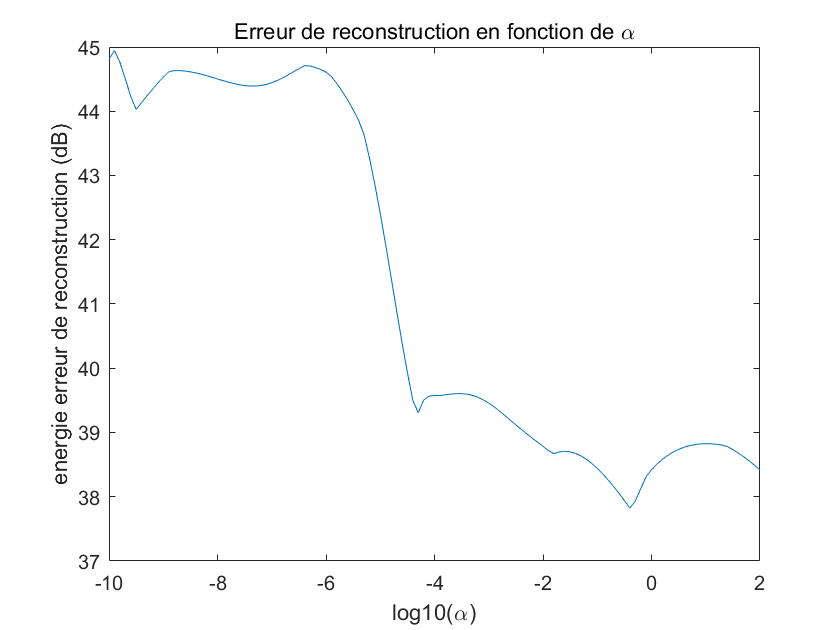


% energie de l'erreur de reconstruction en fonction du coefficient de regularisation
figure
var_alpha1=min_alpha:pas_alpha:max_alpha;
plot(var_alpha1,10*log10(double(Werr_rec1(:))))
xlabel('log10(\alpha)'); ylabel('energie erreur de reconstruction (dB)'); title('Erreur de reconstruction en fonction de \alpha');

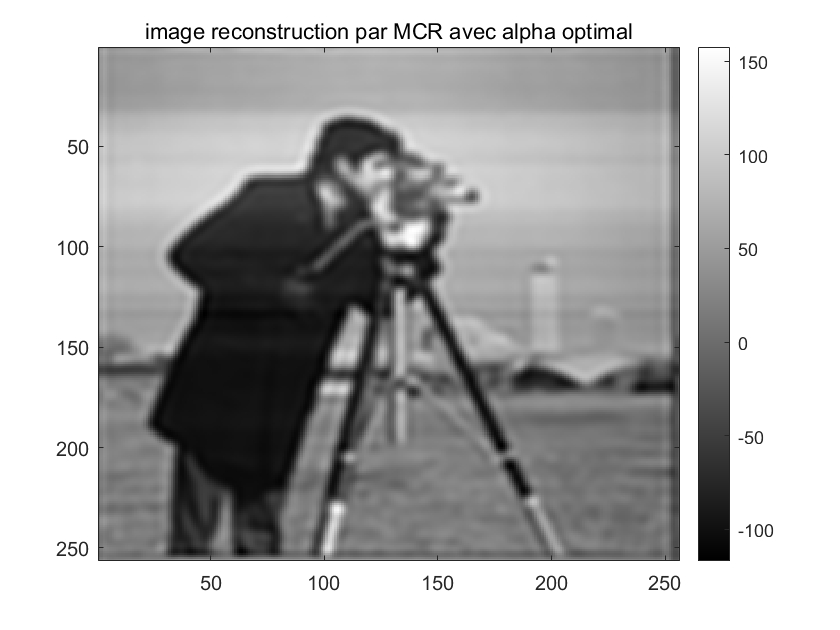


figure,imagesc(A_rec_l2(:,:,i_alpha_opt)),colormap(gray),colorbar,title('image reconstruction par MCR avec alpha optimal')